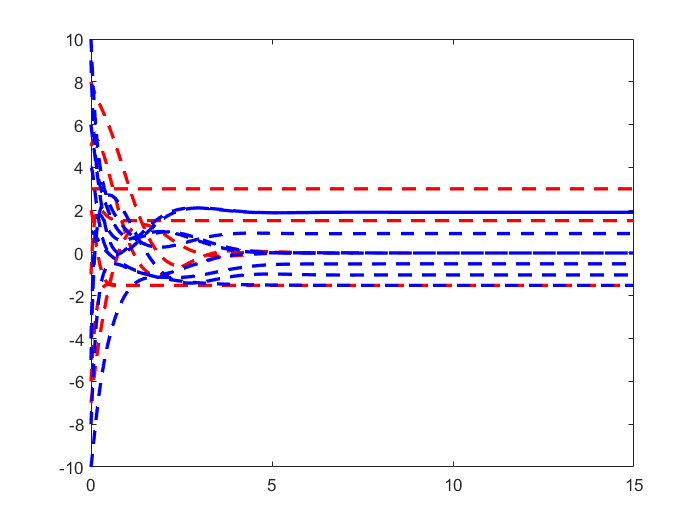

x=[3, 8, -7, 5, 2, -1, -6, 1, 10, 4, -5, 6, -10, 9, -8,-4]';
L =[0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     2     0    -2     0     0     0     0     0     0     0     0     0     0     0     0
     0    -1     1     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     3     3     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     5     5     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     6     6     0     0     0     0     0     0     0     0     0
     0     0     0     0    -4     0     4     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     1     0     1     0     0     0     0     0     0     0     0
     0     0     0    -2     0     0     0     3     5     0     0     0     0     0     0     0
    -4     0     0     0     0     0     0     0     0     9     5     0     0     0     0     0
     0    -6     0     0     0     0     0     0     0     7    13     0     0     0     0     0
     0     0     0     0     0     0     0     0     0    -8     0     8     0     0     0     0
     0     0     0     0    -1     0     0     0     0     0     0     0     3     2     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     5     0    -5
     0     0     3     0     0     0     0     0     0     0     0     0     0     4     7     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     6     6];
[t,y]=ode45(@(t,y)-L*y, [0,15],x);
% plot(t,y,'-')
% plot(t,y(:,1:7))
% title("leader")
% plot(t,y(:,8:16))
% title("follower")
axis manual
xlim([0,15])
ylim([-10,10])
plot(t,y(:,1:7),'--r','LineWidth',2,'MarkerSize',2)
hold on
plot(t,y(:,8:16),'--b','LineWidth',2,'MarkerSize',2)